# Examples 6.7-6.10: Moving Average and Gaussian Filters

Note: this script reproduces Examples 6.7 to 6.10 (Section 6.3.1) of **Statistics for Chemical Engineers**: convolution of a pulse and of a noisy signal with moving-average and Gaussian filters. Victor Z UW-Madison, 2020 illustrate convolutions with different filters

clc;  clear all; close all hidden; format short;

## Pulse signal

create rectangular pulse signal

N = 20;    
w = ones(N,1);
N2= 40;
f = [zeros(N2,1); w; zeros(N2,1)];
Nt = length(f);
t = 0:Nt-1;

## Moving average filter (Example 6.7)

define a moving average filter

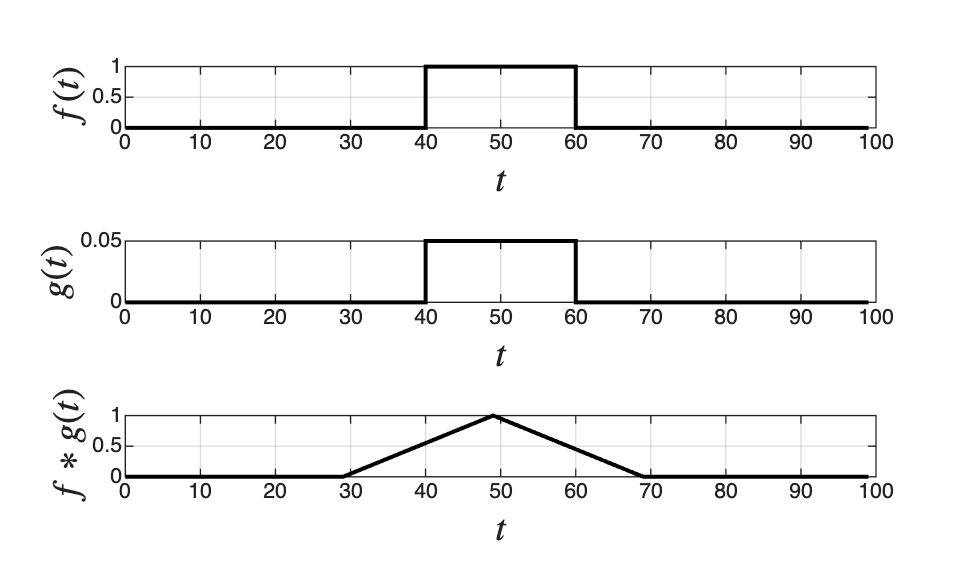

wg=w/N;
gu=[zeros(N2,1); wg; zeros(N2,1)];

% visualize signal and filter
 subplot(3,1,1)
 stairs(t,f,'black','LineWidth',1.5)
 grid on
 ylabel('$f(t)$','Interpreter','Latex','FontSize',14)
 xlabel('$t$','Interpreter','Latex','FontSize',14)
 subplot(3,1,2)
 stairs(t,gu,'black','LineWidth',1.5)
 grid on
 ylabel('$g(t)$','Interpreter','Latex','FontSize',14)
 xlabel('$t$','Interpreter','Latex','FontSize',14)

 % apply convolution
 phi=conv(f,wg,'same'); % can also be done with wg only
 subplot(3,1,3)
 plot(t,phi,'black','LineWidth',1.5)
 grid on
 ylabel('$f*g(t)$','Interpreter','Latex','FontSize',14)
 xlabel('$t$','Interpreter','Latex','FontSize',14)
 
 print -depsc ch6_pulse_average_filter.eps

 
 % check area under curve
 trapz(phi)

ans = 20.0000

## Gaussian filter (Example 6.9)

gauss filter

 alpha = 4; 
 wg = gausswin(N,alpha);
 gg = [zeros(N2,1); wg; zeros(N2,1)];

 figure(2)
 % visualize signal and filter
 subplot(3,1,1)
 stairs(t,f,'black','LineWidth',1.5)
 grid on
 ylabel('$f(t)$','Interpreter','Latex','FontSize',14)
 xlabel('$t$','Interpreter','Latex','FontSize',14)
 subplot(3,1,2)
 plot(t,gg,'black','LineWidth',1.5)
 grid on
 ylabel('$g(t)$','Interpreter','Latex','FontSize',14)
 xlabel('$t$','Interpreter','Latex','FontSize',14)

 subplot(3,1,3)
 phi=conv(f,gg,'same') % can also be done with wg only

phi =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


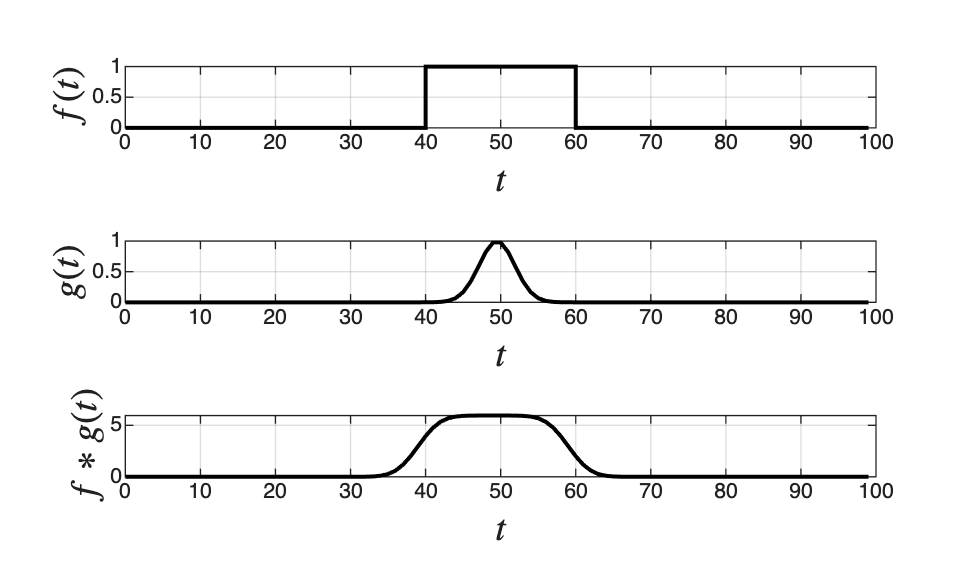

 plot(t,phi,'black','LineWidth',1.5)
 grid on
 ylabel('$f*g(t)$','Interpreter','Latex','FontSize',14)
 xlabel('$t$','Interpreter','Latex','FontSize',14)
 
  print -depsc ch6_pulse_gaussian_filter.eps

  
 % check area under curve
 trapz(phi)

ans = 119.0622

## Noisy signal (Examples 6.8 and 6.10)

apply moving average filter now to a noisy signal

L = 500;                                  % length of signal
Fs= 1000;                                 % Hz (sampling frequency)
T = 1/Fs;                                 % sec (sampling period)
t = (0:L-1)*T;                            % time vector
f1 = sin(2*pi*30*t);                                
f2 = sin(2*pi*60*t);                                       
f = f1+f2;
rng(0);
f = f'+rand(L,1);

 wg=[1/4,1/4,1/4,1/4];
 
 figure(3)
 subplot(3,1,1)
 plot(t,f,'black','LineWidth',1.5)
 grid on
 ylabel('$f(t)$','Interpreter','Latex','FontSize',14)
 xlabel('$t$','Interpreter','Latex','FontSize',14)
 subplot(3,1,2)
 phi=conv(f,wg,'same') % can also be done with wg only

phi =     0.8639
    1.4524
    1.8275
    1.9266
    2.1201
    2.0309
    1.9724
    1.9351
    1.5768
    1.3282
    0.9943
    0.6023
    0.5815
    0.2967
    0.1849


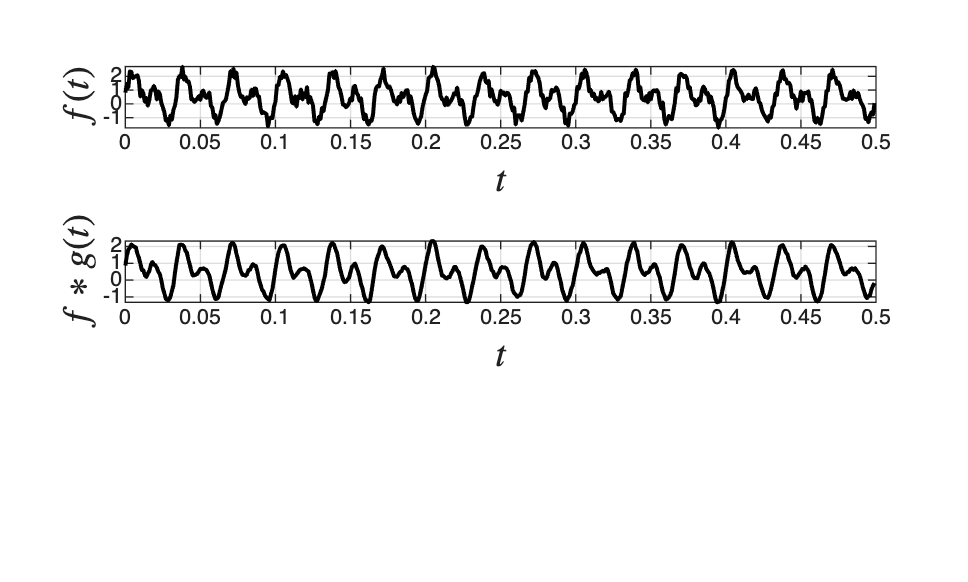

 plot(t,phi,'black','LineWidth',1.5)
 grid on
 ylabel('$f*g(t)$','Interpreter','Latex','FontSize',14)
 xlabel('$t$','Interpreter','Latex','FontSize',14)
 print -depsc ch6_noise_average_filter.eps

## apply moving average filter now to a noisy signal

 figure(4)
 subplot(3,1,1)
 plot(t,f,'black','LineWidth',1.5)
 grid on
 ylabel('$f(t)$','Interpreter','Latex','FontSize',14)
 xlabel('$t$','Interpreter','Latex','FontSize',14)
 
 subplot(3,1,2)
 N=4;
 
 alpha=1;
  
 sigma=(N-1)/(2*alpha)

sigma = 1.5000

  
 wg = gausswin(N,alpha);
 phi=conv(f,wg,'same'); % can also be done with wg only
 plot(t,phi,'black','LineWidth',1.5)
 grid on
 ylabel('$f*g(t)$','Interpreter','Latex','FontSize',14)
 xlabel('$t$','Interpreter','Latex','FontSize',14)
 
 subplot(3,1,3)
 N=4;
 alpha=4;
 sigma=(N-1)/(2*alpha)

sigma = 0.3750

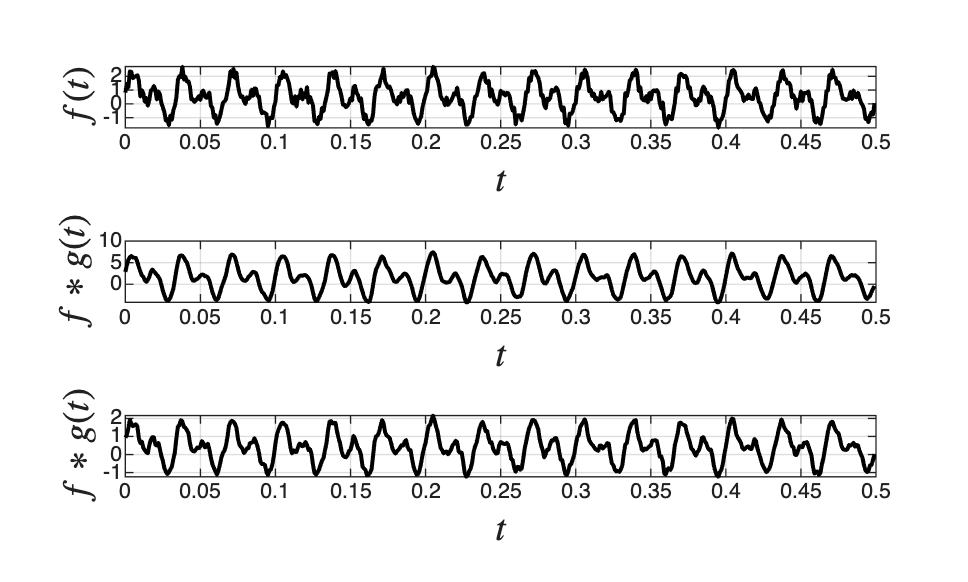

 wg = gausswin(N,alpha);
 phi=conv(f,wg,'same'); % can also be done with wg only
 plot(t,phi,'black','LineWidth',1.5)
 grid on
 ylabel('$f*g(t)$','Interpreter','Latex','FontSize',14)
 xlabel('$t$','Interpreter','Latex','FontSize',14)
 
 print -depsc ch6_noise_gauss_filter.eps

## Note

As in the book, convolution transforms the signal: the filters smooth the pulse and remove noise, and the type and tuning of the filter decide the effect.